# Environment Initialization

close all;
clearvars;
clc;

set(groot,"defaulttextinterpreter","latex");  
set(groot,"defaultAxesTickLabelInterpreter","latex");
set(groot,"defaultLegendInterpreter","latex");

if ~exist("./figures/", "dir")
    mkdir("./figures/");
end

if ~exist("./datasets/", "dir")
    mkdir("./datasets/");
end

# Data Import

Some abbreviations:

- prc -> Percentage -> %

- fcx -> Flotation Column X

*(This Live Script uses a re-parsed version of the dataset so that the numerical columns don't have to be reinterpreted. Modifications are performed by the script in "ds_preprocessing.fish")*

variable_names = ["date", "prc_iron_feed", "prc_silica_feed", ...
    "starch_flow", "amina_flow", "ore_pulp_flow", "ore_pulp_ph", ...
    "ore_pulp_density", "fc1_air_flow", "fc2_air_flow", ...
    "fc3_air_flow", "fc4_air_flow", "fc5_air_flow", "fc6_air_flow", ...
    "fc7_air_flow", "fc1_level", "fc2_level", "fc3_level", "fc4_level", ...
    "fc5_level", "fc6_level", "fc7_level", "prc_iron_concentrate", ...
    "prc_silica_concentrate"];

text_scan_formats = ["%{yyyy-MM-dd HH:mm:ss}D", "%f32", "%f32", "%f32", "%f32", ...
    "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", ...
    "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", "%f32", "%f32"];

ttds = tabularTextDatastore("./datasets/mining_process_database_reformatted.csv", ...
    DatetimeLocale="en_GB", VariableNames=variable_names, NumHeaderLines=1, ...
    Delimiter=";", TextType="string", TextscanFormats=text_scan_formats);

data_table = readall(ttds, UseParallel=true);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


# Invalid data check

As shown below, there is no missing data (some initial reformatting is required, though).

invalid_data = data_table(any(ismissing(data_table), 2), :)


invalid_data =

  0×24 empty table



# Irregular sampling correction

As shown below, there is a period between March 16 at 05:00 and March 29 at 12:00 without any samples being taken.

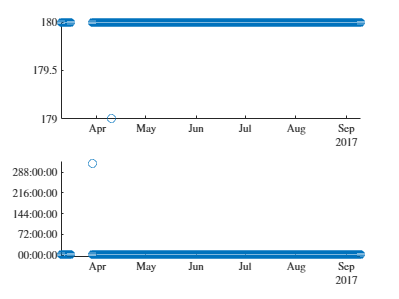

ts_unique = unique(data_table{:, "date"});
ts_count = zeros(size(ts_unique), "uint32");

for ts_idx=1:numel(ts_unique)
    ts_count(ts_idx) = sum(data_table{:, "date"} == ts_unique(ts_idx));
end

figure();
tiledlayout(2,1);
ax = gobjects(2,1);

ax(1) = nexttile();
scatter(ts_unique, ts_count);

ax(2) = nexttile();
scatter(ts_unique(2:end), diff(ts_unique));

linkaxes(ax, "x");
xlim("tight");

Since this happens early on on the timeseries, we decided to omit these samples and drop 3.64% of the dataset in order to ensure dataset reliability.

[~, new_start_idx] = max(diff(data_table{:,"date"}));
data_table_cropped = data_table(new_start_idx+1:end, :);

loss_relative = 1 - height(data_table_cropped)/height(data_table);

We repeat the verification procedure in order to check for further sampling irregularities. As shown below, there is still a timestamp for which we are missing a sample: April 10, at 00:00.

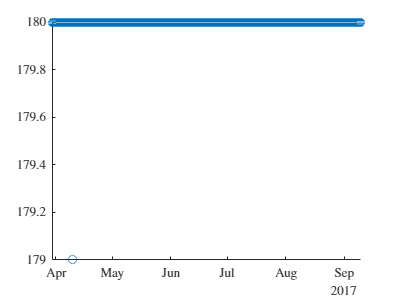

ts_unique_cropped = unique(data_table_cropped{:, "date"});
ts_count_cropped = zeros(size(ts_unique_cropped), "uint32");

for ts_idx=1:numel(ts_unique_cropped)
    ts_count_cropped(ts_idx) = sum(data_table_cropped{:, "date"} == ts_unique_cropped(ts_idx));
end

figure();
scatter(ts_unique_cropped, ts_count_cropped);
xlim("tight");

In order to correct this outlier, we inspect the behaviour of the variables around this timestamp; specifically, we inspect the trends of the *outlet silica concentration* (since it is the variable we ultimately want to model) and the *outlet iron concentration* (since it is described in the reference document as one of the most significative input variables we can use).

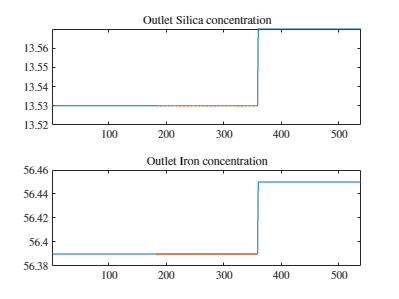

start_idx = find(data_table_cropped{:, "date"} ...
    == datetime(2017, 04, 09, 23, 00, 00), 1, "first");
stop_idx = find(data_table_cropped{:, "date"} ...
    == datetime(2017, 04, 10, 01, 00, 00), 1, "last");

figure();
tiledlayout(2,1);
ax = gobjects(2,1);

ax(1) = nexttile();
plot(data_table_cropped{start_idx:stop_idx, "prc_silica_feed"});
hold on;
plot(181:359, ...
    data_table_cropped{data_table_cropped{:,"date"} ...
        == datetime(2017, 04, 10, 00, 00, 00), ...
    "prc_silica_feed"}, LineWidth=1);
title("Outlet Silica concentration");
hold off;

ax(2) = nexttile();
plot(data_table_cropped{start_idx:stop_idx, "prc_iron_feed"});
hold on;
plot(181:359, ...
    data_table_cropped{data_table_cropped{:,"date"} ...
        == datetime(2017, 04, 10, 00, 00, 00), ...
    "prc_iron_feed"}, LineWidth=1);
title("Outlet Iron concentration");
hold off;

linkaxes(ax, "x");
xlim("tight");

Based on the figures above, we replicate the last sample marked with the irregular timestamp in order to correct the dataset.

insert_idx = find(data_table_cropped{:, "date"} ...
    == datetime(2017, 04, 10, 00, 00, 00), 1, "last");
data_table_regular = [data_table_cropped(1:insert_idx,:);
                        data_table_cropped(insert_idx,:);
                        data_table_cropped(insert_idx+1:end,:)];

We repeat the verification procedure once more in order to check for any remaining irregularities in the timestamps. As expected, none remain.

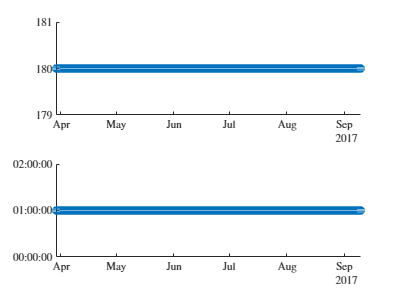

ts_unique_regular = unique(data_table_regular{:, "date"});
ts_count_regular = zeros(size(ts_unique_regular), "uint32");

for ts_idx=1:numel(ts_unique_regular)
    ts_count_regular(ts_idx) = sum(data_table_regular{:, "date"} == ts_unique_regular(ts_idx));
end

figure();
tiledlayout(2,1);
ax = gobjects(2,1);

ax(1) = nexttile();
scatter(ts_unique_regular, ts_count_regular);

ax(2) = nexttile();
scatter(ts_unique_regular(2:end), diff(ts_unique_regular));
ylim([duration(0,0,0), duration(2,0,0)]);

linkaxes(ax, "x");
xlim("tight");

# Timestamp correction

So far, we have talked about how we expect to see 180 samples/timestamp, but we haven't really given an explanation as to why this happens. On the description for the dataset in [Kaggle](https://www.kaggle.com/datasets/edumagalhaes/quality-prediction-in-a-mining-process), we are told that "s*ome columns were sampled every 20 seconds; others were sampled on a hourly base or more.*"; hence why there are 180 (1 hr/20 s) samples per hourly timestamp. The problem with this is that if we want to treat the dataset as a time series, we cannot rely on repeated timestamps; therefore, we do the following manual correction:

- We assume that the first sample of each timestamp was taken exactly at the zeroth second of its corresponding hour.

- We assume that every sample taken after that was captured regularly every 20 seconds, modifying their timestamps incrementally.

Even if we eventually decide to resample the dataset, we export this timetable as it will serve as the new baseline for any data manipulation we do from now on.

Additionally, we save a copy of the dataset sampled hourly, given that the target variable (*outlet silica concentration*) is sampled every 60 minutes, as explained in the dataset description.

ts_regular = data_table_regular{1,"date"}:seconds(20):data_table_regular{end,"date"}+hours(1)-seconds(20);
data_timetable_20s = table2timetable(data_table_regular(:,2:end), ...
    "RowTimes", ts_regular);

writetimetable(data_timetable_20s, "./datasets/dataset_regular_20s.csv", ...
    "DateLocale", "en_GB", "Delimiter", ";");

data_timetable_1h = retime(data_timetable_20s, "hourly", "median");

writetimetable(data_timetable_1h, "./datasets/dataset_regular_1h.csv", ...
    "DateLocale", "en_GB", "Delimiter", ";");

# Down-sampling: Hourly vector

This section deals with the down-sampling the features into hourly vector.

custom_aggregation = @(x) {x};
data_timetable_1h_vector= retime(data_timetable_20s, 'hourly', custom_aggregation);

# Time-series visualisation

With a clearly ordered dataset, we proceed with the data visualisation. We start with the Percentual Iron/Silica time-series which, based on the scope of the project, are expected to be the most relevant.

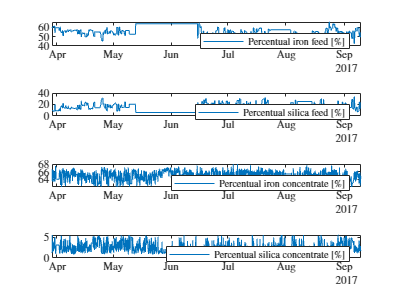

f = figure();
tiledlayout(4,1);
ax = gobjects(4,1);

ax(1) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.prc_iron_feed);
legend("Percentual iron feed $\left[ \% \right]$");

ax(2) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.prc_silica_feed);
legend("Percentual silica feed $\left[ \% \right]$");

ax(3) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.prc_iron_concentrate);
legend("Percentual iron concentrate $\left[ \% \right]$");

ax(4) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.prc_silica_concentrate);
legend("Percentual silica concentrate $\left[ \% \right]$");
linkaxes(ax, "x");
xlim("tight");
exportgraphics(f, "./figures/perc_vars_ts.eps", ...
    Resolution=600);

We can immediately see the issue with this figure: between 13.05.2017 and 15.06.2017 there is no variation in the percentual iron/silica feed, despite the percentual iron/silica concentrate oscillating as in the rest of the timeseries. Such a long period without any change cannot be regarded as a valid measure, and should be immediately discarded if any of those variables is used to calibrate a model. Nevertheless, we could not proceed as we did with the blank period at the beginning of the dataset and simply discard all datapoints before the end of the steady period, since by doing that we would be losing almost half of the total remaining samples. As such, we decided to split the dataset into training/test using this anomaly as the breaking point.

We also plotted the other time-series and looked for similar temporal irregularities, but found none. Thus, the only period removed from the dataset is the one marked by the irregularities in the Percentual Iron/Silica feed timeseries.

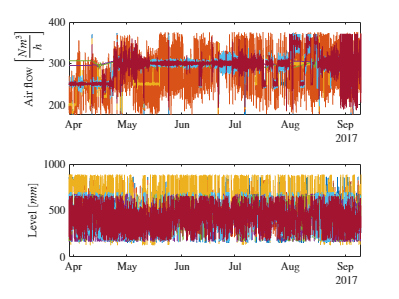

f = figure();
tiledlayout(2,1);
ax = gobjects(2,1);

ax(1) = nexttile();
ax(2) = nexttile();
for i=1:7
    nexttile(1);
    plot(data_timetable_20s.Time, data_timetable_20s.("fc"+string(i)+"_air_flow"));
    hold on;
    
    nexttile(2);
    plot(data_timetable_20s.Time, data_timetable_20s.("fc"+string(i)+"_level"));
    hold on;
end
nexttile(1); ylabel("Air flow $\left[ \frac{N m^3}{h} \right]$"); hold off;
nexttile(2); ylabel("Level $\left[ mm \right]$"); hold off;

linkaxes(ax, "x");
xlim("tight");
exportgraphics(f, "./figures/flotation_columns_ts.eps", ...
    Resolution=600);

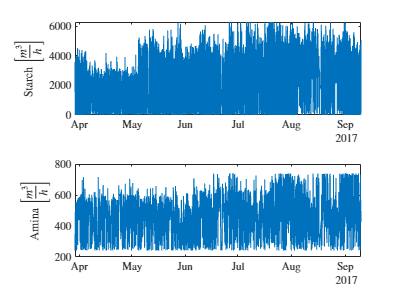

f = figure();
tiledlayout(2,1);
ax = gobjects(2,1);

ax(1) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.starch_flow);
ylabel("Starch $\left[ \frac{m^3}{h} \right]$");

ax(2) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.amina_flow);
ylabel("Amina $\left[ \frac{m^3}{h} \right]$");

linkaxes(ax, "x");
xlim("tight");
exportgraphics(f, "./figures/flow_vars_ts.eps", ...
    Resolution=600);

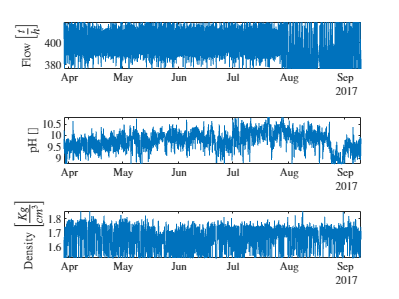

f = figure();
tiledlayout(3,1);
ax = gobjects(3,1);

ax(1) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.ore_pulp_flow);
ylabel("Flow $\left[ \frac{t}{h} \right]$")

ax(2) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.ore_pulp_ph);
ylabel("pH $[]$");

ax(3) = nexttile();
plot(data_timetable_20s.Time, data_timetable_20s.ore_pulp_density);
ylabel("Density $\left[ \frac{Kg}{{cm}^3} \right]$");

linkaxes(ax, "x");
xlim("tight");
exportgraphics(f, "./figures/ore_pulp_vars_ts.eps", ...
    Resolution=600);

# Variable distribution visualisation

With the above "mask" in mind, we proceeded with the variable distribution visualisation process, for which we used both box-plots (when scale grouping made physical sense) and histograms (when variables were either too different on scale or belonged to unrelated physical categories).

mask = ~(data_timetable_20s.Time >= datetime(2017, 05, 13) ...
            & data_timetable_20s.Time < datetime(2017, 06, 15));

first_removed = find(~mask, 1, "first");
last_removed = find(~mask, 1, "last");

test_ratio = (first_removed - 1) / sum(mask);
train_ratio = (numel(mask) - last_removed) / sum(mask);

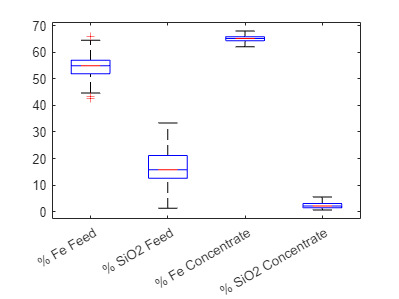

f = figure();
boxplot(data_timetable_20s(mask, ...
        ["prc_iron_feed", ...
        "prc_silica_feed", ...
        "prc_iron_concentrate", ...
        "prc_silica_concentrate"]).Variables, ...
    ["% Fe Feed", "% SiO2 Feed", ...
        "% Fe Concentrate", "% SiO2 Concentrate"], ...
    "Notch", "on");
exportgraphics(f, "./figures/perc_vars_bp.eps", ...
    Resolution=600);

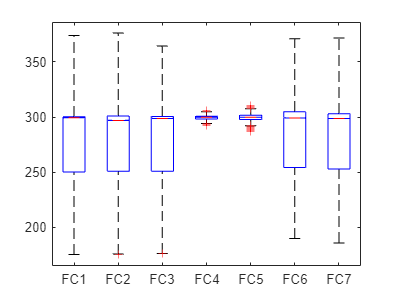

f = figure();
boxplot(data_timetable_20s(mask, 8:14).Variables, ...
    strcat("FC", string(1:7)), ...
    "Notch", "on");
exportgraphics(f, "./figures/FC_airflow_bp.eps", ...
    Resolution=600);

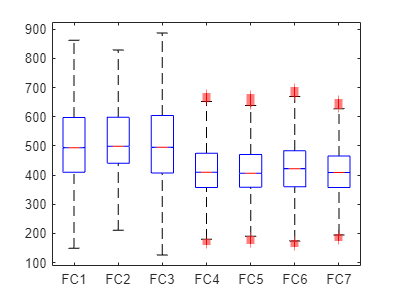

f = figure();
boxplot(data_timetable_20s(mask, 15:21).Variables, ...
    strcat("FC", string(1:7)), ...
    "Notch", "on");
exportgraphics(f, "./figures/FC_level_bp.eps", ...
    Resolution=600);

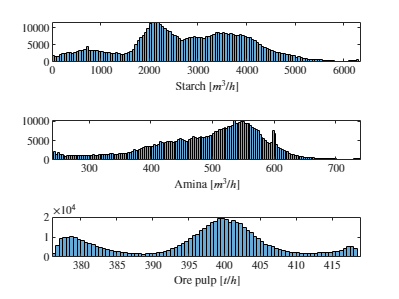

f = figure();
tiledlayout("vertical");

nexttile();
histogram(data_timetable_20s(mask, "starch_flow").Variables);
xlabel("Starch $\left[ m^3/h \right]$"); xlim("tight");

nexttile();
histogram(data_timetable_20s(mask, "amina_flow").Variables);
xlabel("Amina $\left[ m^3/h \right]$"); xlim("tight");

nexttile();
histogram(data_timetable_20s(mask, "ore_pulp_flow").Variables);
xlabel("Ore pulp $\left[ t/h \right]$"); xlim("tight");

exportgraphics(f, "./figures/flow_hist.eps", ...
    Resolution=600);

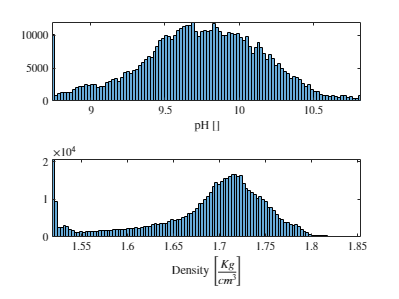

f = figure();
tiledlayout("vertical");

nexttile();
histogram(data_timetable_20s(mask, "ore_pulp_ph").Variables);
xlabel("pH $[]$"); xlim("tight");

nexttile();
histogram(data_timetable_20s(mask, "ore_pulp_density").Variables);
xlabel("Density $\left[ \frac{Kg}{{cm}^3} \right]$"); xlim("tight");

exportgraphics(f, "./figures/ore_pulp_hist.eps", ...
    Resolution=600);

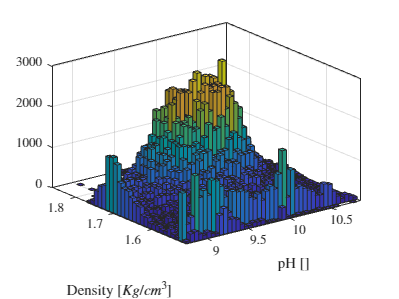

f = figure();
histogram2(data_timetable_20s(mask, "ore_pulp_ph").Variables, ...
    data_timetable_20s(mask, "ore_pulp_density").Variables, ...
    "FaceColor", "flat");

xlabel("pH []"); xlim("tight")
ylabel("Density $\left[ Kg/{cm}^3 \right]$"); ylim("tight");

exportgraphics(f, "./figures/ore_pulp_hist2.eps", ...
    Resolution=600);

# Centred Visualisation

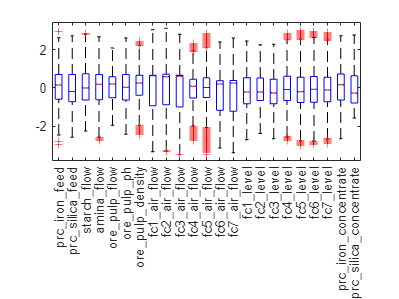

data_timetable_20s_filtered = data_timetable_20s(mask, :);
data_timetable_20s_norm = normalize(data_timetable_20s_filtered, "zscore");

f = figure();
boxplot(data_timetable_20s_norm.Variables, ...
    data_timetable_20s_norm.Properties.VariableNames, ...
    "Notch", "on");

exportgraphics(f, "./figures/norm_vars_bp.eps", ...
    Resolution=600);